### **Question 01**

hhconst;

amp1 = 6;
width1 = 1;
hhmplot(0,50,0);

amp1 = 7;
hhmplot(0,50,1);

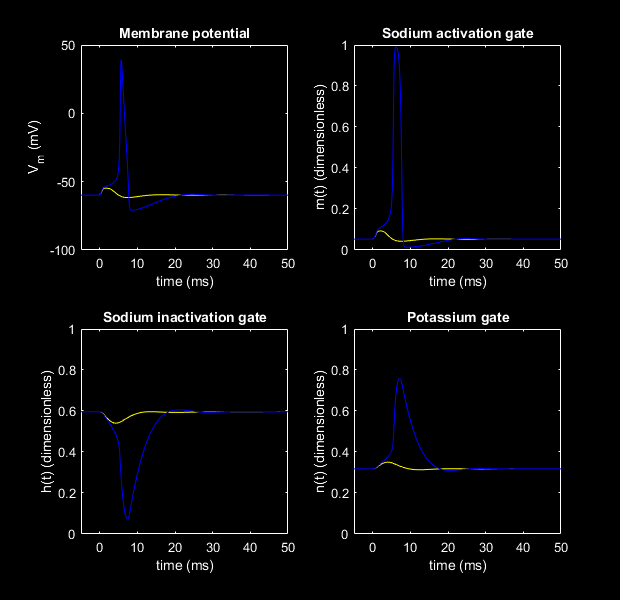

sup_thres = 7;
sub_thres = 6;


bisec(sub_thres, sup_thres,0.01);
disp("Estimated Threshold is "+round(amp1,2)+" micro Ampere per square centimetres")

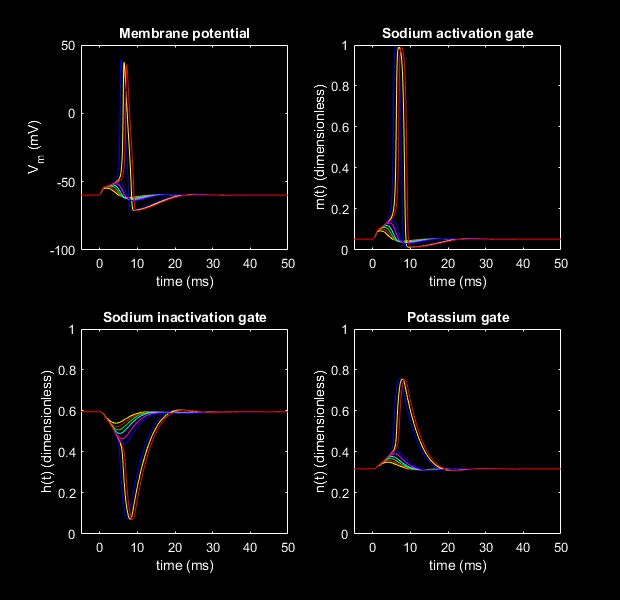

When ampliude = 6.5-->-53.9948
When ampliude = 6.75-->-53.262
When ampliude = 6.875-->-52.5262
When ampliude = 6.9375-->-51.562
When ampliude = 6.9688-->37.4533
When ampliude = 6.9531-->-50.7059
When ampliude = 6.9609-->35.8031


hhmplot(0,50,0);

### **Question 02**

[qna,qk,ql]=hhsplot(0,50);

Estimated Threshold is 6.96 micro Ampere per square centimetres


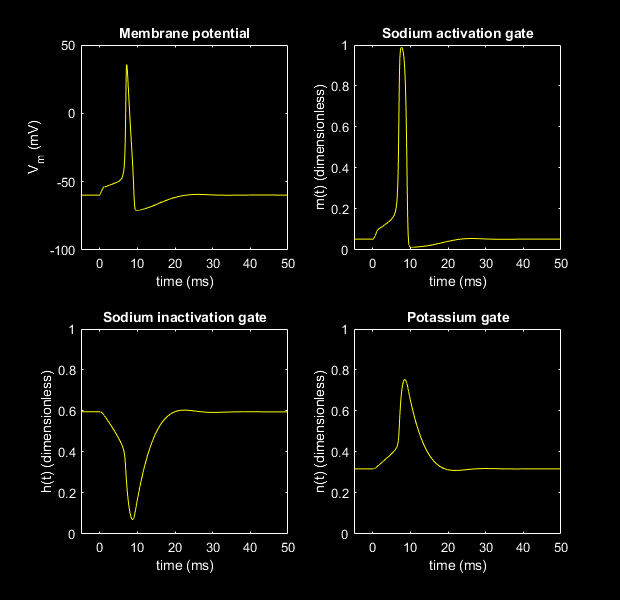

disp("qna + qk + ql = "+ (qna+qk+ql));
disp("qei = "+ (amp1*width1))

Now we can see that the summation of ionic chargers in K, Na and leak channels is equal to the summation of stimulating chargers.

### **Question 03**

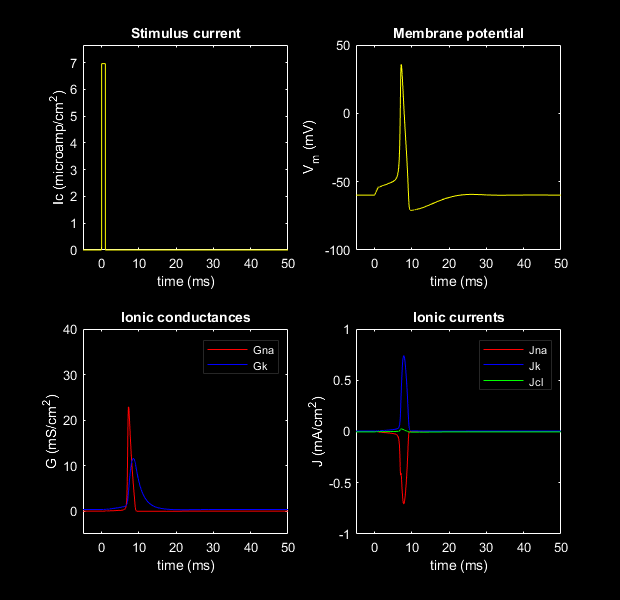

% When delay2 = 20
amp1 = 26.8;

width1 = 0.5; 

qna + qk + ql = 6.9617


width2 = 0.5;

qei = 6.9609


delay2 = 20;

sup_thres = 11.5625;
sub_thres = 11.5313;
amp2 = (sup_thres + sub_thres) / 2;
maximum_error = sup_thres-sub_thres;
if maximum_error < 0.1
    disp("Accuracy achieved");
end
disp("Given amplitude = "+round(amp2,1));
hhsplot(0,40); 

% When delay2 = 18
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 18;

sup_thres = 11.3125;

Accuracy achieved


sub_thres = 11.25;

Given amplitude = 11.5


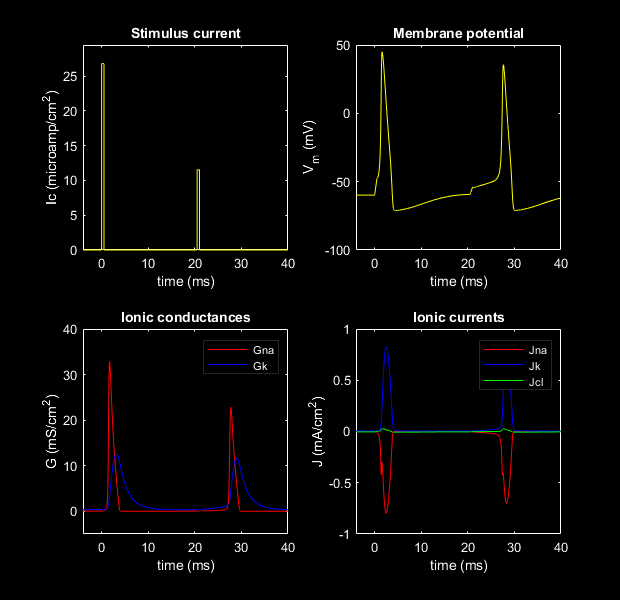

amp2 = (sup_thres + sub_thres) / 2;

maximum_error = sup_thres-sub_thres;
if maximum_error < 0.1
    disp("Accuracy achieved");
end
disp("Given amplitude = "+amp2);
hhsplot(0,40); 

% When delay2 = 16
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 16;

sup_thres = 12.75;
sub_thres = 12.6875;

Accuracy achieved


amp2 = (sup_thres + sub_thres) / 2; 

Given amplitude = 11.2813


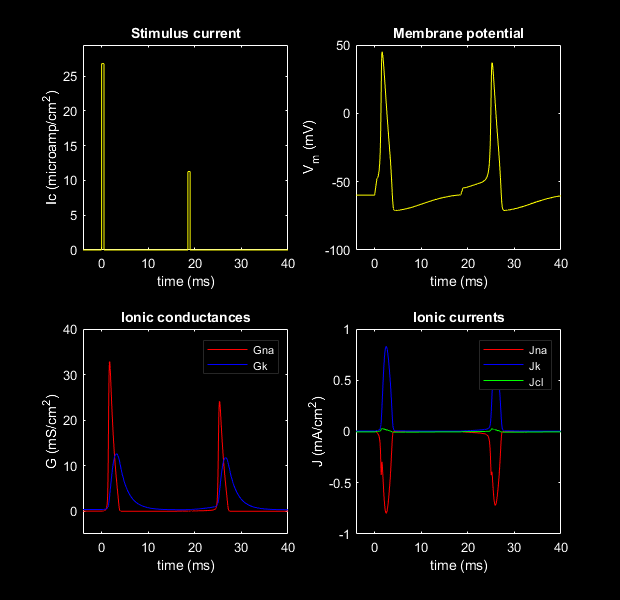

maximum_error = sup_thres-sub_thres;

if maximum_error < 0.1
    disp("Accuracy achieved");
end
disp("Given amplitude = "+amp2);
hhsplot(0,40); 

% When delay2 = 14
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 14;

sup_thres = 16.9375;
sub_thres = 16.9063;
amp2 = (sup_thres + sub_thres) / 2;

Accuracy achieved


maximum_error = sup_thres-sub_thres;

Given amplitude = 12.7188


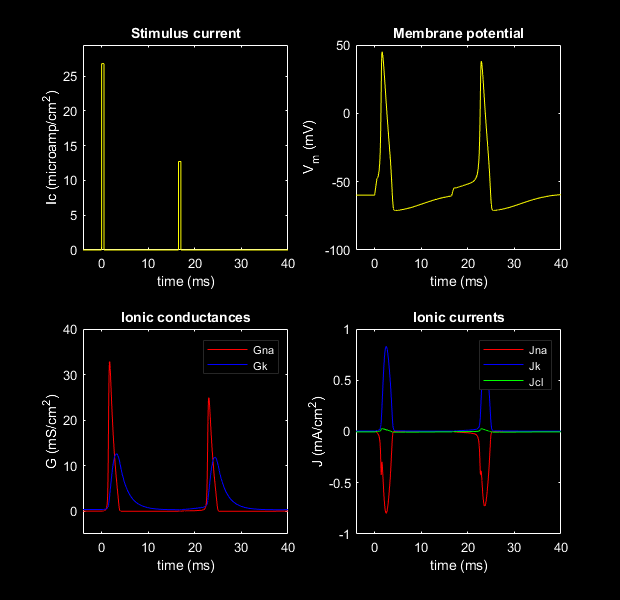

if maximum_error < 0.1

    disp("Accuracy achieved");
end
disp("Given amplitude = "+amp2);
hhsplot(0,40); 

% When delay2 = 12
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 12;

sup_thres = 25.4375;
sub_thres = 25.4063;
amp2 = (sup_thres + sub_thres) / 2;
maximum_error = sup_thres-sub_thres;

Accuracy achieved


if maximum_error < 0.1

Given amplitude = 16.9219


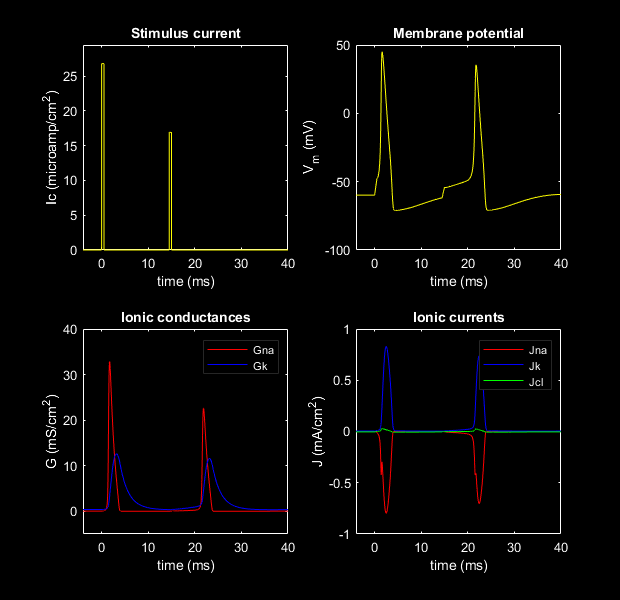

    disp("Accuracy achieved");

end
disp("Given amplitude = "+amp2);
hhsplot(0,40); 

% When delay2 = 10
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 10;

sup_thres = 40.75;
sub_thres = 40.6875;
amp2 = (sup_thres + sub_thres) / 2;
maximum_error = sup_thres-sub_thres;
if maximum_error < 0.1

Accuracy achieved


    disp("Accuracy achieved");

Given amplitude = 25.4219


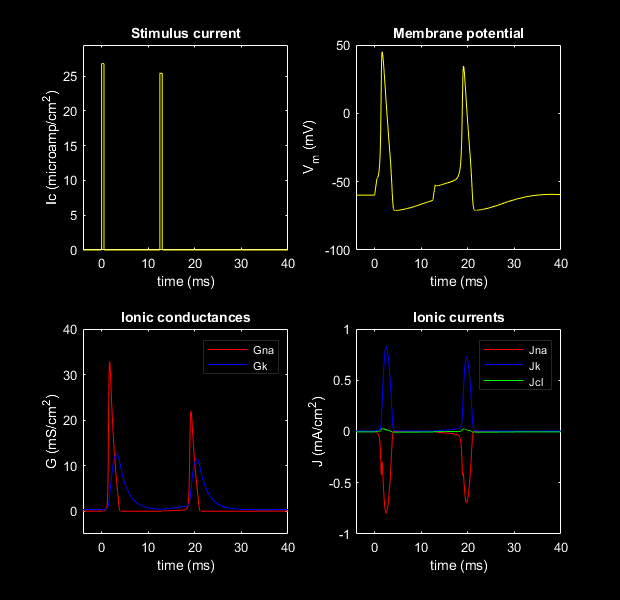

end

disp("Given amplitude = "+amp2);
hhsplot(0,40); 

% When delay2 = 8
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 8;

sup_thres = 70.125;
sub_thres = 70.0625;
amp2 = (sup_thres + sub_thres) / 2; 
maximum_error = sup_thres-sub_thres;
if maximum_error < 0.1
    disp("Accuracy achieved");

Accuracy achieved


end

Given amplitude = 40.7188


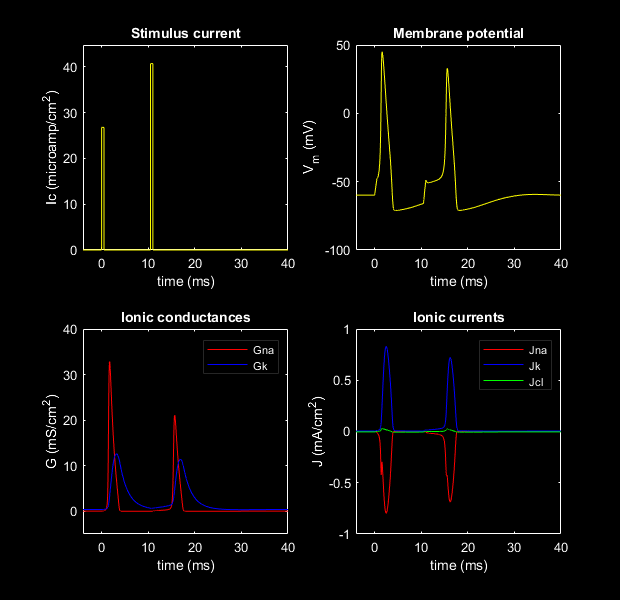

disp("Given amplitude = "+amp2);

hhsplot(0,40); 

% When delay2 = 6
amp1 = 26.8;
width1 = 0.5; 
width2 = 0.5;
delay2 = 6;

sup_thres = 145.2344;
sub_thres = 145.1563;
amp2 = (sup_thres + sub_thres) / 2;
maximum_error = sup_thres-sub_thres;
if maximum_error < 0.1
    disp("Accuracy achieved");
end

Accuracy achieved


disp("Given amplitude = "+amp2);

Given amplitude = 70.0938


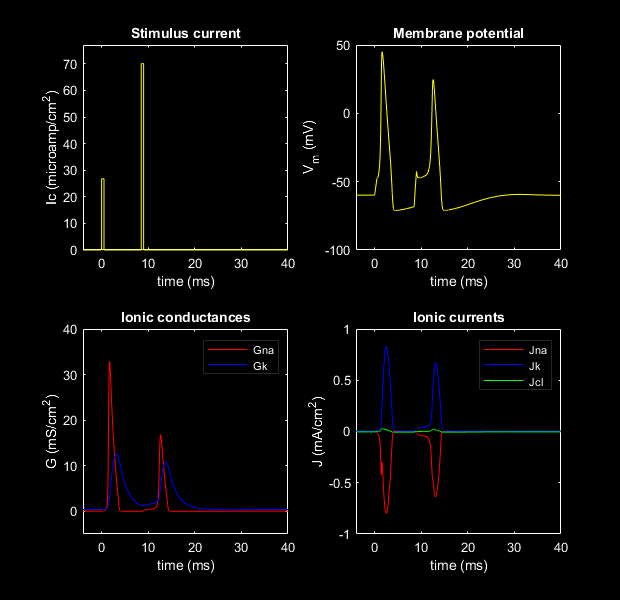

hhsplot(0,40); 

Please see*** fitModel.ipynb*** file to see how I derived an approximate model to the relationship between current threshold and the inter stimulus time period.

figure;
t = [6,8,10,12,14,16,18,20];
thresholds = [145.2,  70.1,  40.7,  25.4,  16.9,  12.7,  11.3,  11.5];
tt = linspace(5,21,100);
yy = 1387.6*exp(-0.39*tt)+11;

plot(t,thresholds,'o'); hold on; grid on;
title('approx. Relationship between current threshold and the inter stimulus time period')
xlabel("Interstimulus Time")
ylabel("Thrshold value for second pulse generation")
plot(tt,yy)
hold off;

Accuracy achieved


### **Question 4**

I1th = 13.4;

Given amplitude = 145.1953


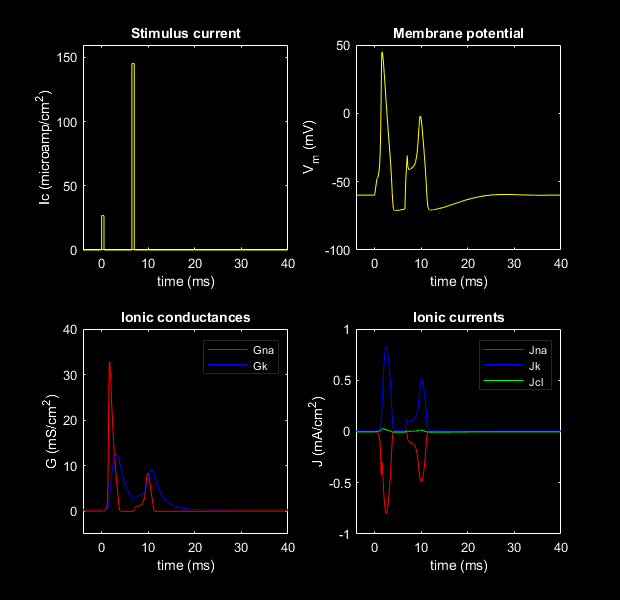

I2th_I1th_ratio = thresholds/I1th;

plot(t,I2th_I1th_ratio,'x'); hold on;
plot(tt, yy/I1th,'b')
title("Approx model -->  103.552 exp(-0.39t) + 0.82")
t1 = log(0.18/(1387.6/13.4))/(-0.39)
a = linspace(4,t1,100);
b = ones(1,100);
stem(t1,1);
plot(a,b);
grid on;
hold off;

The sodium gates are opened with the start of first action potential and then start to close during the repolarization. When the potassium channels fully opened, the Na gates are almost closed and the time is around 3.188 ms. Threfore, the absolute refactory period is nearly 0ms - 3.188ms. From the above plot, we can see that the threshold is more than 15 times the initial threshold. 

Then starts the relative refactory period. There we can initiate a second action potential with the expense of a high stimulus current. The stimulus current we need becomes equal to the first stimulus current value, when the time is around, 16.946 ms according to the above calculations and the plot. Threfore, the relative refactory period is nearly from 3.188ms to 16.946 ms.

**Absolute refactory period ---> nearly 0 ms to 3.188 ms**

**Relative refactory period ----> nearly 3.188 ms to 16.946 ms**

### **Question 04**

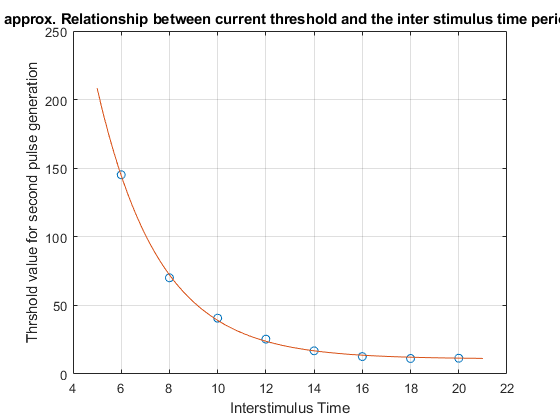

amp1 = 100;
width1 = 80;
delay2 = 0;
amp2 = 0;
width2 = 0;

hhmplot(0,100,0);

% Here, I initiate an array for number of action potential triggers in a
% period of 80ms

in_80ms = [1,6,7,8,10,11,12];
in_1s = in_80ms / (80*10^-3);
amplitudes = [5,10,20,30,50,70,100];
for i=1:7
    disp("When amplitude = "+amplitudes(i)+", action potential frequency = "+in_1s(i))

t1 = 16.2946

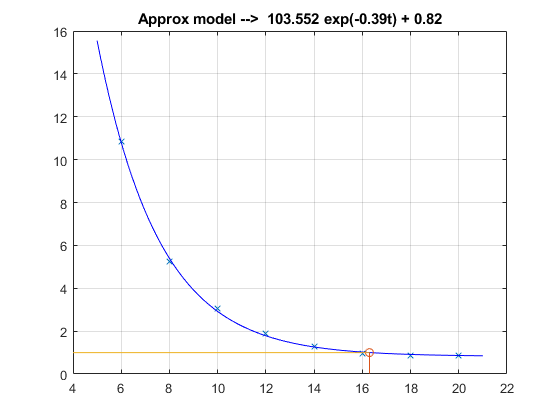

end
figure;
plot(amplitudes,in_1s,'x')
title("Action potential frequency as a function of stimulating current amplitude");
xlabel("Stimulating current amplitude µAcm-2");
ylabel("Action potoential frequency (occurings per second)")

xlim([0.0 105.0])
ylim([0 160])

In every case, the first action potential has a significantly higher amplitude than the next set of action potentials.

When the stimulus intensity amplitude increases, the action potential amplitude decreases. But the first action potential has only a little deviation compared to the other action potentials after it, in every case.

### Question 06

amp1 = 200;
hhmplot(0,100,0)

### **Question 07**

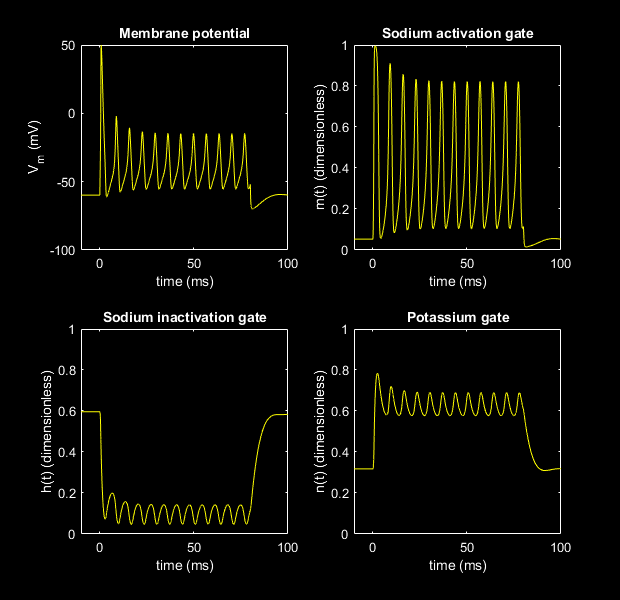

vclamp = 0;
amp1 = 20;
width1 = 0.5;
tempc = 30;

When amplitude = 5, action potential frequency = 12.5
When amplitude = 10, action potential frequency = 75
When amplitude = 20, action potential frequency = 87.5
When amplitude = 30, action potential frequency = 100
When amplitude = 50, action potential frequency = 125
When amplitude = 70, action potential frequency = 137.5
When amplitude = 100, action potential frequency = 150


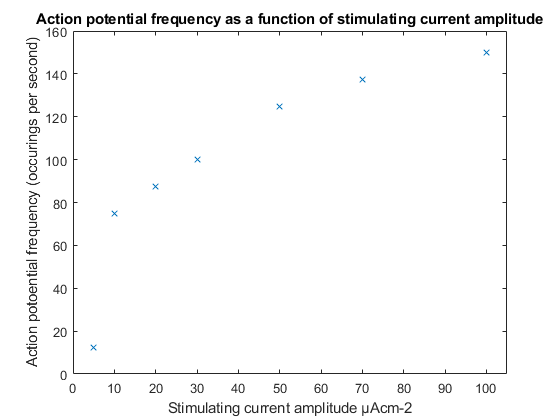

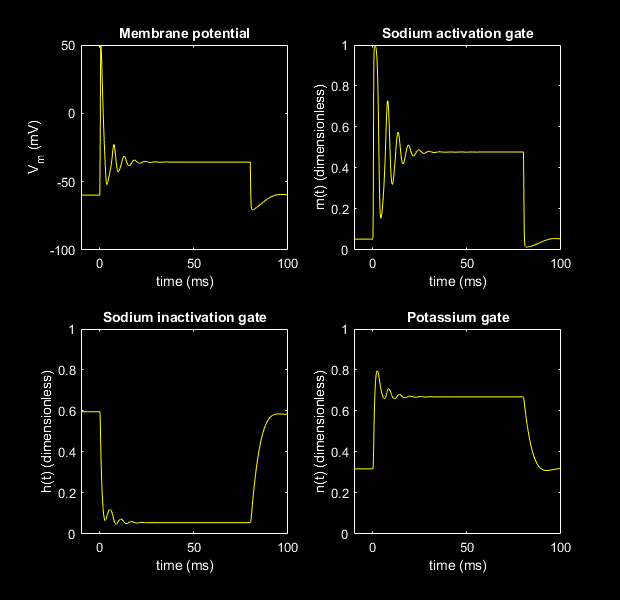

ans = 53.6770

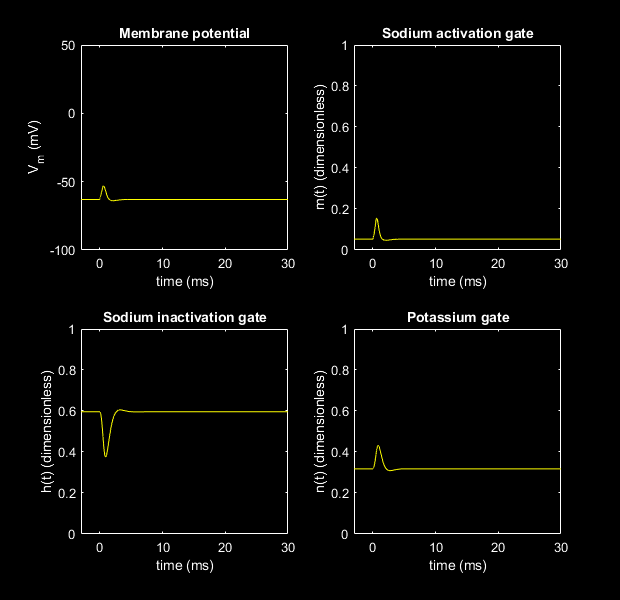

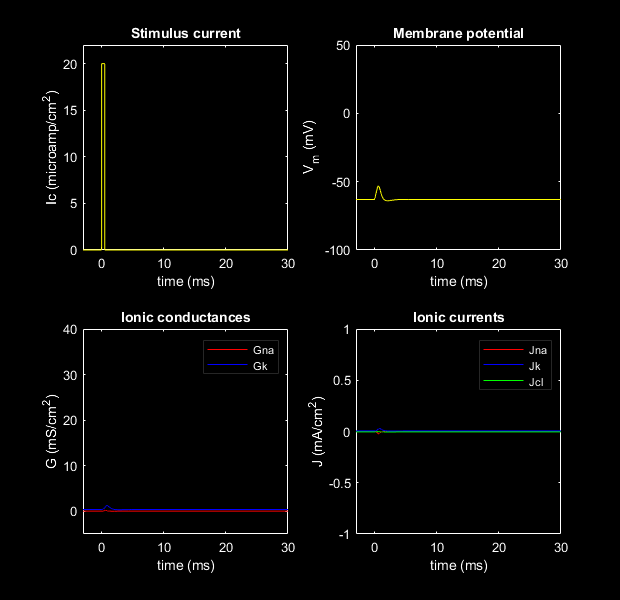

hhmplot(0,30,0);
hhsplot(0,30);
